#  Initialization

clear all;

% accel data
% accelerometer = load("X02299_ConflictTaskRun1.mat"); % dirty
accelerometer = load("acc_run1.mat");
sampling = 1 / (accelerometer.headers.graph.dSampleTime / 1000);

% cued data
% cued_data = load('02299_1_2022_Oct_06_1223_V_cued_r_time.mat'); % dirty
cued_data = load('1330_1_2021_Jul_13_1449_V_cued_r_time.mat');
cued_data.stimonset = round(cued_data.stimonset * 1000);
cued_data.presstime = round(cued_data.presstime * 1000);

# Filtering

% Isolating vibration at 75 nd 175 Hz
cutoff_low = 170; 
cutoff_high = 180; 
filter_order = 5;

[b, a] = butter(filter_order, [cutoff_low/(sampling/2), cutoff_high/(sampling/2)], 'bandpass');

vibration = filtfilt(b, a , accelerometer.data);

cutoff_low = 220; 
cutoff_high = 230; 
filter_order = 5;

[b, a] = butter(filter_order, [cutoff_low/(sampling/2), cutoff_high/(sampling/2)], 'bandpass');

insert = filtfilt(b, a , accelerometer.data);
vibration = vibration + insert;

filter_order = 3;
cutoff_low = 5;
[b,a] = butter(filter_order, cutoff_low/(sampling/2), 'low');

vibration_envelope = filtfilt(b,a, abs(vibration));
vibration_envelope(:,1) = vibration_envelope(:,1) * 30;
vibration_envelope(:,4) = vibration_envelope(:,4) * 10;

% Isolating movement
cutoff_low = 1; 
cutoff_high = 10; % around maximum of non trained human movement
filter_order = 1;

[b, a] = butter(filter_order, [cutoff_low/(sampling/2), cutoff_high/(sampling/2)], 'bandpass');

movement = abs(filtfilt(b, a , accelerometer.data));

filter_order = 3;
cutoff_low = 5;
[b,a] = butter(filter_order, cutoff_low/(sampling/2), 'low');

movement_envelope = filtfilt(b,a, abs(movement));
movement_envelope(:,2) = movement_envelope(:,2) * 20;
movement_envelope(:,4) = movement_envelope(:,4) * 10;

% FFT
fft_raw = fft(accelerometer.data);
fft_movement = fft(movement);
fft_vibration = fft(vibration);
f = (1:length(fft_raw)) * sampling / length(fft_raw);

% find peaks and borders for vibration
min_peak_distance = 2000;

[vibration_peaks_fdi, vibration_peaks_locs_fdi] = findpeaks(vibration_envelope(:,1), 'MinPeakProminence',0.4, 'MinPeakDistance',2e3);
[vibration_peaks_adm, vibration_peaks_locs_adm] = findpeaks(vibration_envelope(:,4), 'MinPeakProminence',0.5, 'MinPeakDistance',2e3);

minSignalLevel = [min(vibration_envelope(:,1)), min(vibration_envelope(:,4))];
thresholds_fdi = minSignalLevel(1) + 0.2 * (vibration_peaks_fdi - minSignalLevel(1));
thresholds_adm = minSignalLevel(2) + 0.2 * (vibration_peaks_adm - minSignalLevel(2));

borders_fdi = zeros(length(vibration_peaks_locs_fdi),2);
for i = 1:length(vibration_peaks_locs_fdi)
    peakPos = vibration_peaks_locs_fdi(i);
    leftBorder = find(vibration_envelope(1:peakPos, 1) < thresholds_fdi(i), 1, 'last');
    rightBorder = find(vibration_envelope(peakPos:end, 1) < thresholds_fdi(i), 1, 'first') + peakPos - 1;
    if isempty(leftBorder)
        leftBorder = 1;
    end
    if isempty(rightBorder)
        rightBorder = length(vibration_envelope(:, 1));
    end
    borders_fdi(i,:) = [leftBorder, rightBorder];
end

borders_adm = zeros(length(vibration_peaks_locs_fdi),2);
for i = 1:length(vibration_peaks_locs_adm)
    peakPos = vibration_peaks_locs_adm(i);
    leftBorder = find(vibration_envelope(1:peakPos, 4) < thresholds_adm(i), 1, 'last');
    rightBorder = find(vibration_envelope(peakPos:end, 4) < thresholds_adm(i), 1, 'first') + peakPos - 1;
    if isempty(leftBorder)
        leftBorder = 1;
    end
    if isempty(rightBorder)
        rightBorder = length(vibration_envelope(:, 4));
    end
    borders_adm(i,:) = [leftBorder, rightBorder];
end

% avg finger vibration intensity (x most sensitive) -> get out outliers -> no false positives
length(vibration_peaks_fdi)

ans = 216

borders_fdi = borders_fdi(vibration_peaks_fdi > mean(vibration_peaks_fdi) - 0.7 * std(vibration_peaks_fdi), :);
vibration_peaks_locs_fdi = vibration_peaks_locs_fdi(vibration_peaks_fdi > mean(vibration_peaks_fdi) - 0.7 * std(vibration_peaks_fdi), :);
vibration_peaks_fdi = vibration_peaks_fdi(vibration_peaks_fdi > mean(vibration_peaks_fdi) - 0.7 * std(vibration_peaks_fdi));
length(vibration_peaks_fdi)

ans = 135

length(borders_fdi)

ans = 135


length(vibration_peaks_adm)

ans = 129

borders_adm = borders_adm(vibration_peaks_adm > mean(vibration_peaks_adm) - 1.7 * std(vibration_peaks_adm), :);
vibration_peaks_locs_adm = vibration_peaks_locs_adm(vibration_peaks_adm > mean(vibration_peaks_adm) - 1.7 * std(vibration_peaks_adm), :);
vibration_peaks_adm = vibration_peaks_adm(vibration_peaks_adm > mean(vibration_peaks_adm) - 1.7 * std(vibration_peaks_adm));
length(vibration_peaks_adm)

ans = 119

length(borders_adm)

ans = 119


length(borders_fdi) + length(borders_adm)

ans = 254

length(cued_data.stimonset)

ans = 253


% remove double detections
collaged = sort([borders_fdi(:,1); borders_adm(:,1)]);
length(collaged)

ans = 254


find(diff(collaged) <  min_peak_distance) % less than 3s

ans =     30
    52
    61
    69
    73
    75
   104
   121
   124
   133


test = (sort([borders_fdi(:,1); borders_adm(:,1)]));
test(67)

ans = 268724


temp = diff((sort([borders_fdi(:,1); borders_adm(:,1)])));
temp(67)

ans = 4022


% 0 not detected, 1 fdi, 2 adm vibration
vibration_onset = zeros(length(collaged),1);
for i = 1:length(vibration_onset)
    if ismember(collaged(i), borders_fdi(:,1))
        vibration_onset(i) = 1;
    end
    if ismember(collaged(i), borders_adm(:,1))
        vibration_onset(i) = 2;
    end
    if i > 1 && (collaged(i) - collaged(i-1) < min_peak_distance) % exclude the consecutive findings
        vibration_onset(i) = 3;
    end
end
vibration_onset = vibration_onset(vibration_onset ~= 3);
length(vibration_onset)

ans = 229

% find peaks and borders for movement

[movement_peaks_fdi, movement_peaks_locs_fdi] = findpeaks(movement_envelope(:,2), 'MinPeakProminence',0.3, 'MinPeakDistance',2e3);
[movement_peaks_adm, movement_peaks_locs_adm] = findpeaks(movement_envelope(:,4), 'MinPeakProminence',0.5, 'MinPeakDistance',2e3);

minSignalLevel = [min(movement_envelope(:,2)), min(movement_envelope(:,4))];
thresholds_fdi = minSignalLevel(1) + 0.2 * (movement_peaks_fdi - minSignalLevel(1));
thresholds_adm = minSignalLevel(2) + 0.2 * (movement_peaks_adm - minSignalLevel(2));

borders_fdi_m = zeros(length(movement_peaks_locs_fdi),2);
for i = 1:length(movement_peaks_locs_fdi)
    peakPos = movement_peaks_locs_fdi(i);
    leftBorder = find(movement_envelope(1:peakPos, 2) < thresholds_fdi(i), 1, 'last');
    rightBorder = find(movement_envelope(peakPos:end, 2) < thresholds_fdi(i), 1, 'first') + peakPos - 1;
    if isempty(leftBorder)
        leftBorder = 1;
    end
    if isempty(rightBorder)
        rightBorder = length(movement_envelope(:, 2));
    end
    borders_fdi_m(i,:) = [leftBorder, rightBorder];
end

borders_adm_m = zeros(length(movement_peaks_locs_adm),2);
for i = 1:length(movement_peaks_locs_adm)
    peakPos = movement_peaks_locs_adm(i);
    leftBorder = find(movement_envelope(1:peakPos, 4) < thresholds_adm(i), 1, 'last');
    rightBorder = find(movement_envelope(peakPos:end, 4) < thresholds_adm(i), 1, 'first') + peakPos - 1;
    if isempty(leftBorder)
        leftBorder = 1;
    end
    if isempty(rightBorder)
        rightBorder = length(movement_envelope(:, 4));
    end
    borders_adm_m(i,:) = [leftBorder, rightBorder];
end

# Isolated vibration plot

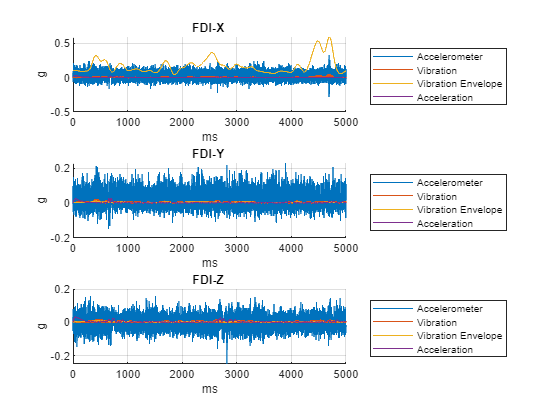

figure() 
t = linspace(0, length(accelerometer.data(:,1))/2, length(accelerometer.data(:,1)));
for i = 1:length(accelerometer.data(1,:))/2
    subplot(3,1,i)

    % Find peaks and borders to detect vibration
    
    hold on
    plot(t,accelerometer.data(:,i)-median(accelerometer.data(:,i)))
    plot(t,abs(vibration(:,i)))
    plot(t,vibration_envelope(:,i))
    plot(t,movement(:,i))
    scatter(t(vibration_peaks_locs_fdi), vibration_peaks_fdi)
    scatter(t(borders_fdi(:,1)), vibration_envelope(borders_fdi(:,1),i), marker = "x", LineWidth=2)
    scatter(t(borders_fdi(:,2)), vibration_envelope(borders_fdi(:,2),i), marker = "x", LineWidth=2)
    hold off

    title(accelerometer.labels(i,1:6))
    ylabel(accelerometer.units(i))
    xlabel(accelerometer.isi_units)
    xlim([0,1e4/2])
    grid("on")
    legend("Accelerometer", "Vibration", "Vibration Envelope", "Acceleration",'Location','eastoutside')
end

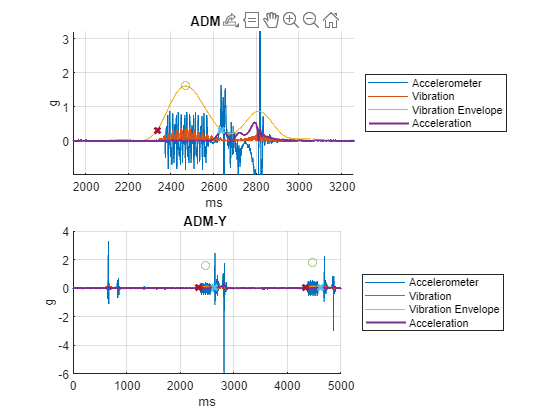


figure()

for i = 4:length(accelerometer.data(1,:))-1
    subplot(2,1,i-3)
    
    % Find peaks and borders to detect vibration
    
    hold on
    plot(t,accelerometer.data(:,i)-median(accelerometer.data(:,i)))
    plot(t,abs(vibration(:,i)))
    plot(t,vibration_envelope(:,i))
    plot(t,movement(:,i), 'LineWidth',1.5)
    scatter(t(vibration_peaks_locs_adm), vibration_peaks_adm)
    scatter(t(borders_adm(:,2)), vibration_envelope(borders_adm(:,2),i), marker = "x", LineWidth=2)
    scatter(t(borders_adm(:,1)), vibration_envelope(borders_adm(:,1),i), marker = "x", LineWidth=2)
    hold off

    title(accelerometer.labels(i,1:6))
    ylabel(accelerometer.units(i))
    xlabel(accelerometer.isi_units)
    xlim([0e4,1e4/2])
    grid("on")
    legend("Accelerometer", "Vibration", "Vibration Envelope","Acceleration",'Location','eastoutside')
end

# Isolated movement plot

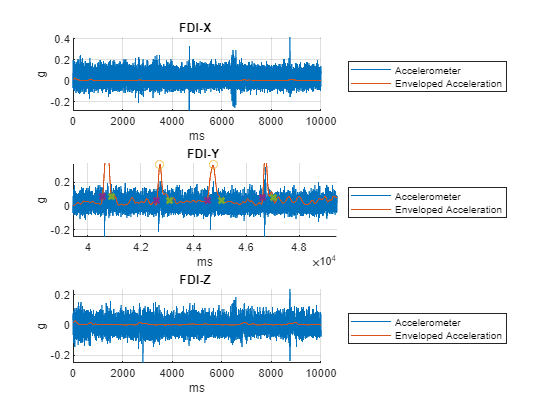

figure() % first maximum of derivative to check t find movement
% find movement from vibration segmenting into timewindows from vibration
% csv with output
% check
% reference ideas
% abstract, discussion *suggestions, pay attention to data acquisition

t = linspace(0, length(accelerometer.data(:,1))/2, length(accelerometer.data(:,1)));
for i = 1:length(accelerometer.data(1,:))/2
    subplot(3,1,i)
    
    hold on
    plot(t,accelerometer.data(:,i)-median(accelerometer.data(:,i)))
    plot(t,movement_envelope(:,i))
    scatter(t(movement_peaks_locs_fdi), movement_peaks_fdi)
    scatter(t(borders_fdi_m(:,1)), movement_envelope(borders_fdi_m(:,1),i), marker = "x", LineWidth=2)
    scatter(t(borders_fdi_m(:,2)), movement_envelope(borders_fdi_m(:,2),i), marker = "x", LineWidth=2)
    hold off

    title(accelerometer.labels(i,1:6))
    ylabel(accelerometer.units(i))
    xlabel(accelerometer.isi_units)
    xlim([0,1e4])
    grid("on")
    legend("Accelerometer", "Enveloped Acceleration",'Location','eastoutside')
end

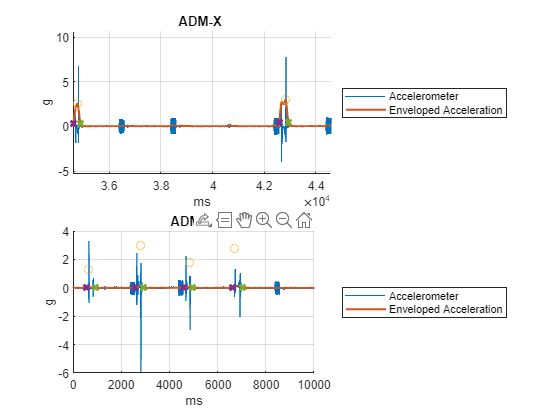


figure()

for i = 4:length(accelerometer.data(1,:))-1
    subplot(2,1,i-3)
    
    hold on
    plot(t,accelerometer.data(:,i)-median(accelerometer.data(:,i)))
    plot(t,movement_envelope(:,i), 'LineWidth',1.5)
    scatter(t(movement_peaks_locs_adm), movement_peaks_adm)
    scatter(t(borders_adm_m(:,1)), movement_envelope(borders_adm_m(:,1),i), marker = "x", LineWidth=2)
    scatter(t(borders_adm_m(:,2)), movement_envelope(borders_adm_m(:,2),i), marker = "x", LineWidth=2)
    hold off

    title(accelerometer.labels(i,1:6))
    ylabel(accelerometer.units(i))
    xlabel(accelerometer.isi_units)
    xlim([0e4,1e4])
    grid("on")
    legend("Accelerometer", "Enveloped Acceleration",'Location','eastoutside')
end

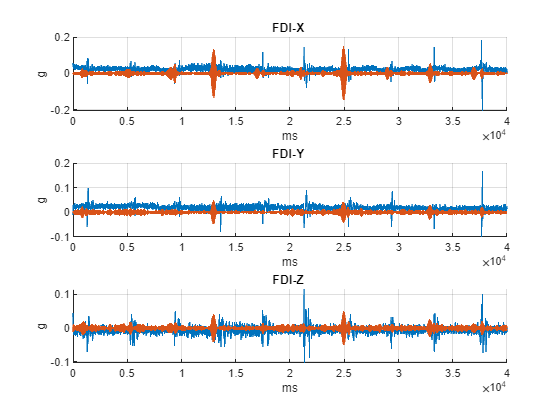

cutoff = 50;
filter_order = 1;
[b, a] = butter(filter_order, cutoff/(sampling/2), 'low');

filtered400 = filtfilt(b,a, accelerometer.data);

filtered400 = filtered400 - median(filtered400);

cutoff_low = 170; 
cutoff_high = 180; 
filter_order = 5;

[b, a] = butter(filter_order, [cutoff_low/(sampling/2), cutoff_high/(sampling/2)], 'bandpass');

vibration_check = filtfilt(b,a, accelerometer.data);

cutoff_low = 220; 
cutoff_high = 230; 
filter_order = 5;

[b, a] = butter(filter_order, [cutoff_low/(sampling/2), cutoff_high/(sampling/2)], 'bandpass');

insert = filtfilt(b, a , accelerometer.data);
vibration_check = vibration_check + insert;

figure()

for i = 1:length(accelerometer.data(1,:))/2
    subplot(3,1,i)
    
    hold on
    plot(filtered400(:,i))
    plot(vibration_check(:,i))
    hold off

    title(accelerometer.labels(i,1:6))
    ylabel(accelerometer.units(i))
    xlabel(accelerometer.isi_units)
    xlim([0,4e4])
    grid("on")
    % legend("Vibration", "Acceleration", "mean movement", "mean acceleration", 'mean + std', 'Location','eastoutside')
end

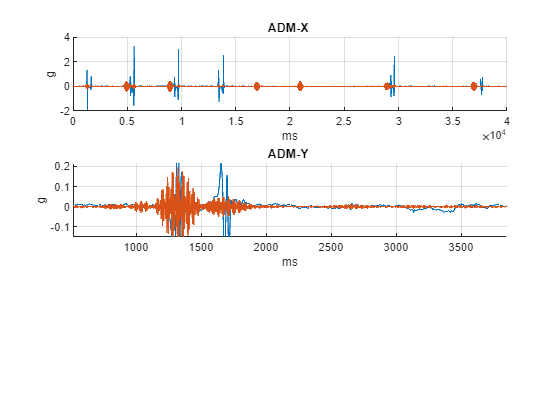


figure()

for i = 4:length(accelerometer.data(1,:))-1
    subplot(3,1,i-3)
    
    hold on
    plot(filtered400(:,i))
    plot(vibration_check(:,i))
    hold off

    title(accelerometer.labels(i,1:6))
    ylabel(accelerometer.units(i))
    xlabel(accelerometer.isi_units)
    xlim([0,4e4])
    grid("on")
    % legend("Vibration", "Acceleration", "mean movement", "mean acceleration", 'mean + std', 'Location','eastoutside')
end % figure out onset vibrations -> segment

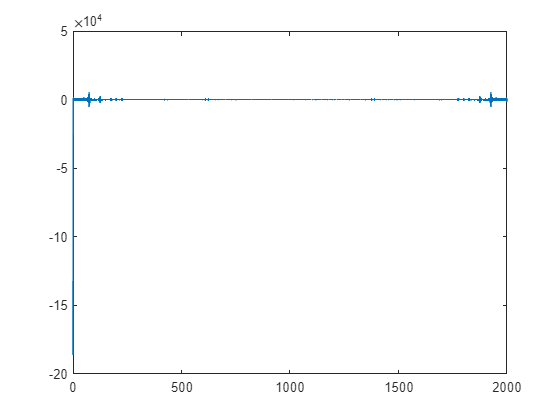

% ignore first trial -> from second onwards
% select vibration for each finger. SNR
% x = ms. 1s before next vibration. should have 200 segments
% onset conditions -> segmentation
% fz vibration >> movement
% list of onsets -> finger -> trial -> summary statistics
fft_vibration_check = fft(vibration_check);

figure()
plot(f, fft_raw(:, 5))

# 3.1 Segmenting

timewindows = [cued_data.stimonset(1:end-1);... % every vibration is my starting point
    cued_data.stimonset(2:end)];
timewindows = [timewindows [cued_data.stimonset(end); length(accelerometer.data(:,1))]];

baseline = abs(movement)

baseline =     0.0277    0.0193    0.0066    0.0034    0.0006    0.0003
    0.0285    0.0210    0.0062    0.0033    0.0005    0.0002
    0.0292    0.0226    0.0059    0.0033    0.0003    0.0001
    0.0300    0.0242    0.0055    0.0032    0.0002    0.0001
    0.0307    0.0259    0.0051    0.0031    0.0000    0.0002
    0.0314    0.0275    0.0048    0.0030    0.0001    0.0003
    0.0321    0.0290    0.0044    0.0030    0.0002    0.0004
    0.0327    0.0306    0.0040    0.0029    0.0004    0.0006
    0.0334    0.0322    0.0036    0.0028    0.0005    0.0007
    0.0340    0.0337    0.0032    0.0027    0.0007    0.0008


# Plotting

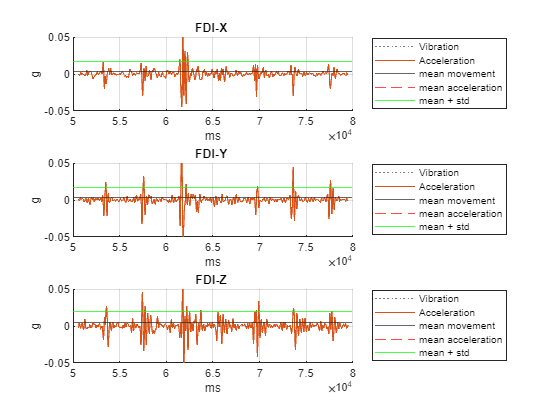

figure()

for i = 1:length(accelerometer.data(1,:))/2
    subplot(3,1,i)
    
    window = movement(timewindows(1,1):timewindows(1,7), i);
    vibration_window = vibration(timewindows(1,1):timewindows(1,7), i);
    t = linspace(timewindows(1,1), timewindows(1,7), length(window));
    
    hold on
    plot(t, vibration_window, 'LineStyle',':', 'Color', [0.5 0.5 0.5])
    plot(t, window)
    yline(mean(abs(movement(:,i))))
    yline(mean(abs(vibration(:,i))),'Color','r', LineStyle='--')
    yline(mean(abs(movement(:,i))) + 2 * std(movement(:,i)), 'Color', 'g')
    ylim([-0.05, 0.05])
    hold off

    title(accelerometer.labels(i,1:6))
    ylabel(accelerometer.units(i))
    xlabel(accelerometer.isi_units)
    grid("on")
    legend("Vibration", "Acceleration", "mean movement", "mean acceleration", 'mean + std', 'Location','eastoutside')
end

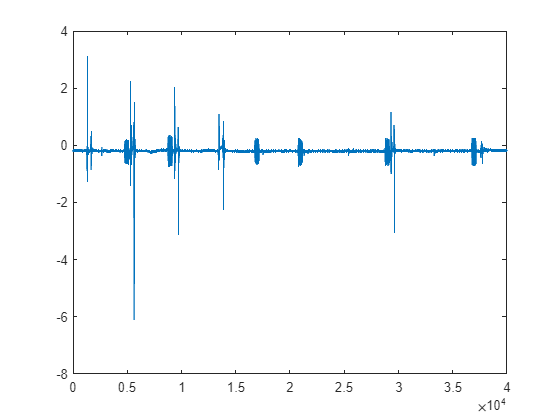

figure()

plot(accelerometer.data(:,5))
% xlim([0,0.5e5]) % -6 touch
xlim([0,4e4])

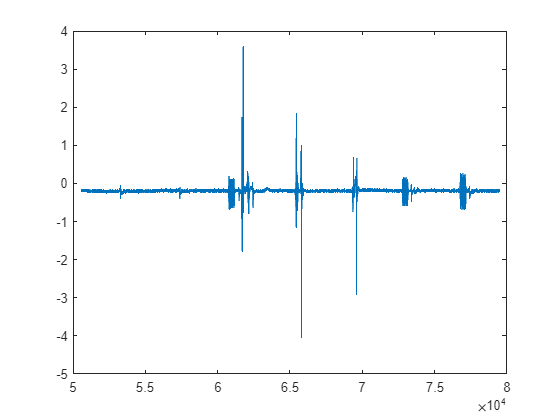

window = accelerometer.data(timewindows(1,1):timewindows(1,7), 5);
vibration_window = vibration(timewindows(1,1):timewindows(1,7), 5);
t = linspace(timewindows(1,1), timewindows(1,7), length(window));
plot(t, window)

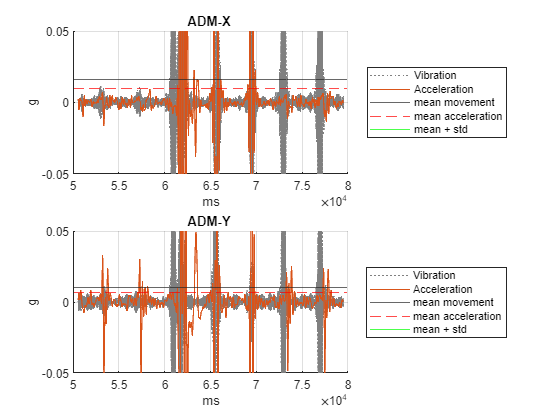


figure()
for i = 4:length(accelerometer.data(1,:))-1 % last channel not working
    subplot(2,1,i-3)
    
    window = movement(timewindows(1,1):timewindows(1,7), i);
    vibration_window = vibration(timewindows(1,1):timewindows(1,7), i);
    t = linspace(timewindows(1,1),timewindows(1,7),length(window));

    hold on
    plot(t, vibration_window, 'LineStyle',':', 'Color', [0.5 0.5 0.5])
    plot(t, window)
    yline(mean(abs(movement(:,i))))
    yline(mean(abs(vibration(:,i))),'Color','r', LineStyle='--')
    yline(mean(abs(movement(:,i))) + 2 * std(movement(:,i)), 'Color', 'g')
    hold off
    
    title(accelerometer.labels(i,1:6))
    ylabel(accelerometer.units(i))
    xlabel(accelerometer.isi_units)
    ylim([-0.05, 0.05])
    grid("on")
    legend("Vibration", "Acceleration", "mean movement", "mean acceleration",'mean + std', 'Location','eastoutside')
end

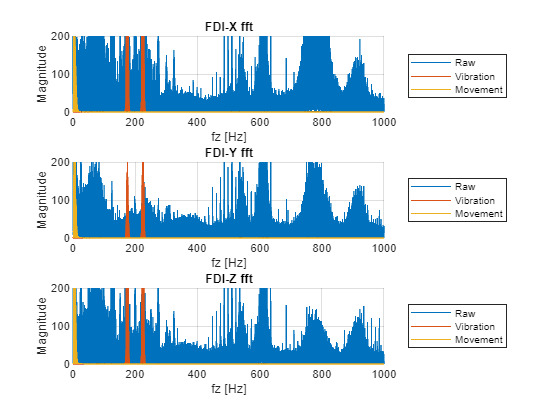

figure() %l 400
for i = 1:length(accelerometer.data(1,:))/2 % last channel not working
    subplot(3,1,i)
    
    hold on
    plot(f, abs(fft_raw(:,i)))
    plot(f, abs(fft_vibration(:,i)))
    plot(f, abs(fft_movement(:,i)))
    hold off

    title(accelerometer.labels(i,1:6) + "fft")
    ylabel('Magnitude')
    xlabel('fz [Hz]')
    grid("on")
    ylim([0,200])
    xlim([0,1000])
    legend("Raw", "Vibration", "Movement", 'Location','eastoutside')
end

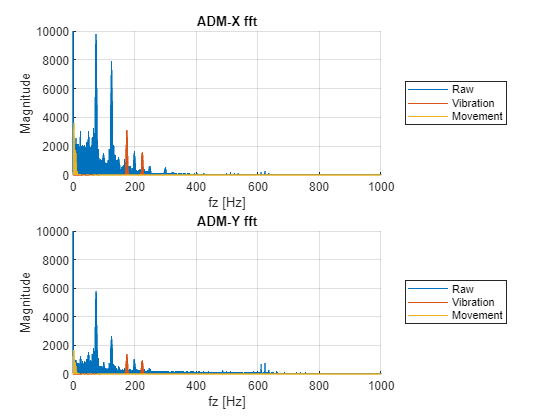

figure()
for i = 4:length(accelerometer.data(1,:))-1 % last channel not working
    subplot(2,1,i-3)
    
    hold on
    plot(f, abs(fft_raw(:,i)))
    plot(f, abs(fft_vibration(:,i)))
    plot(f, abs(fft_movement(:,i)))
    hold off

    title(accelerometer.labels(i,1:6) + "fft")
    ylabel('Magnitude')
    xlabel('fz [Hz]')
    grid("on")
    ylim([0,10000])
    xlim([0,1000])
    legend("Raw", "Vibration", "Movement", 'Location','eastoutside')
end

mean_accel_adm = mean(abs(movement(:,5))); % Y axis of ADM
mean_accel_fdi = mean(abs(movement(:,2))); % Y axis of FDI
std_accel_fdi = std(movement(:,2));

% ADM (2) or FDI (1) 
predicted_response = zeros(length(timewindows(1,:)),1);
correct_fdi = 0;
correct_adm = 0;

for i=1:240 % index error if length(timewindows(1,:))-1?
    start = timewindows(1,i);
    finish = timewindows(2,i);

    % current_mean_fdi = mean(abs(movement(start:finish, 2)));
    % current_mean_adm = mean(abs(movement(start:finish, 5)));
    current_max_fdi = max(abs(movement(start:finish, 2)));
    current_max_adm = max(abs(movement(start:finish, 5)));

    if current_max_fdi > mean_accel_fdi %+ 2 * std_accel_fdi
        predicted_response(i) = 1;
        if cued_data.stimname(i) == 2 || cued_data.stimname(i) == 3
            correct_fdi = correct_fdi + 1;
        end
    end

    if current_max_adm > mean_accel_adm
        predicted_response(i) = 2;
        if cued_data.stimname(i) == 1 || cued_data.stimname(i) == 4
            correct_adm = correct_adm + 1;
        end
    end
end

disp("Correct fdi guesses: " + correct_fdi/length(find(predicted_response == 1)));

Correct fdi guesses: 0


disp("Correct adm guesses: "  + correct_adm/length(find(predicted_response == 2)));

Correct adm guesses: 0



% mean_vibration = mean()
% predicted_test = zeros(length(cued_data.stimname)); % 0 -> rest
% 
% predicted_test()